# PCA - MATLAB (N dimensiones)

Autor: Diego Vértiz Padilla Este script aplica PCA a datos con múltiples variables. Calcula la varianza explicada y proyecta los datos en las componentes principales necesarias.



% Cargar datos
data = readtable("bci_clean_pca.csv");
data.Empleado = [];  % Eliminar columna no numérica

% Convertir tabla a matriz
X = table2array(data);

% Eliminar columnas con NaN
X(:, any(isnan(X))) = [];

% Centrar datos
X_centered = X - mean(X);

% Matriz de covarianza y correlación
disp("Matriz de covarianza:");

Matriz de covarianza:


disp(cov(X_centered));

   1.0e+03 *

    0.2205    0.1221    0.1633    0.2245    0.1578    0.2430    0.2203    0.2505
    0.1221    0.1485    0.1479    0.1316    0.1395    0.0193    0.0565   -0.0103
    0.1633    0.1479    0.2248    0.2048    0.1878    0.0721    0.1173    0.0231
    0.2245    0.1316    0.2048    0.3049    0.2014    0.3459    0.2971    0.3649
    0.1578    0.1395    0.1878    0.2014    0.1877    0.1053    0.1436    0.0800
    0.2430    0.0193    0.0721    0.3459    0.1053    0.9359    0.6072    1.1042
    0.2203    0.0565    0.1173    0.2971    0.1436    0.6072    0.4799    0.7225
    0.2505   -0.0103    0.0231    0.3649    0.0800    1.1042    0.7225    1.3870




disp("Matriz de correlación:");

Matriz de correlación:


disp(corrcoef(X_centered));

    1.0000    0.6746    0.7337    0.8660    0.7754    0.5348    0.6774    0.4529
    0.6746    1.0000    0.8095    0.6186    0.8357    0.0517    0.2115   -0.0226
    0.7337    0.8095    1.0000    0.7825    0.9144    0.1571    0.3572    0.0413
    0.8660    0.6186    0.7825    1.0000    0.8417    0.6476    0.7769    0.5612
    0.7754    0.8357    0.9144    0.8417    1.0000    0.2511    0.4784    0.1568
    0.5348    0.0517    0.1571    0.6476    0.2511    1.0000    0.9060    0.9691
    0.6774    0.2115    0.3572    0.7769    0.4784    0.9060    1.0000    0.8856
    0.4529   -0.0226    0.0413    0.5612    0.1568    0.9691    0.8856    1.0000




% Aplicar PCA
[coeff, score, latent, ~, explained] = pca(X_centered, 'Centered', false);

% Varianza explicada
disp("Varianza explicada (%):");

Varianza explicada (%):


disp(explained');

   75.5301   19.8357    1.3861    1.1245    0.9651    0.5288    0.4170    0.2127




% Varianza acumulada
var_acum = cumsum(explained) / 100;
disp("Varianza acumulada:");

Varianza acumulada:


disp(var_acum');

    0.7553    0.9537    0.9675    0.9788    0.9884    0.9937    0.9979    1.0000




% Determinar número de componentes necesarios para ≥95% varianza
n95 = find(var_acum >= 0.95, 1);
fprintf("Componentes necesarios para ≥95%% varianza: %d\n", n95);

Componentes necesarios para ≥95% varianza: 2



% Matriz proyectada Z
Z = score(:, 1:n95);
disp("Matriz proyectada Z:");

Matriz proyectada Z:


disp(Z(1:5, :));  % Mostrar primeras filas

  -11.2770  -13.4721
  -11.8035  -14.9616
  -14.9247  -18.9864
  -12.2656  -18.6674
   -4.8355  -14.7272



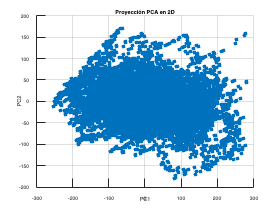


figure;
scatter(Z(:,1), Z(:,2), 60, 'filled');
xlabel('PC1'); ylabel('PC2');
title('Proyección PCA en 2D');
grid on;